Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |       37.50% |       52.46% |       1.0919 |       1.1753 |          0.0010 |
|       1 |           5 |       00:00:02 |       84.38% |       65.57% |       1.1257 |       2.0063 |          0.0010 |
|       2 |          10 |       00:00:03 |       93.75% |       63.93% |       0.5947 |       0.9036 |          0.0010 |
|       3 |          15 |       00:00:04 |      100.00% |       65.57% |       0.3853 |       0.6225 |          0.0010 |
|       

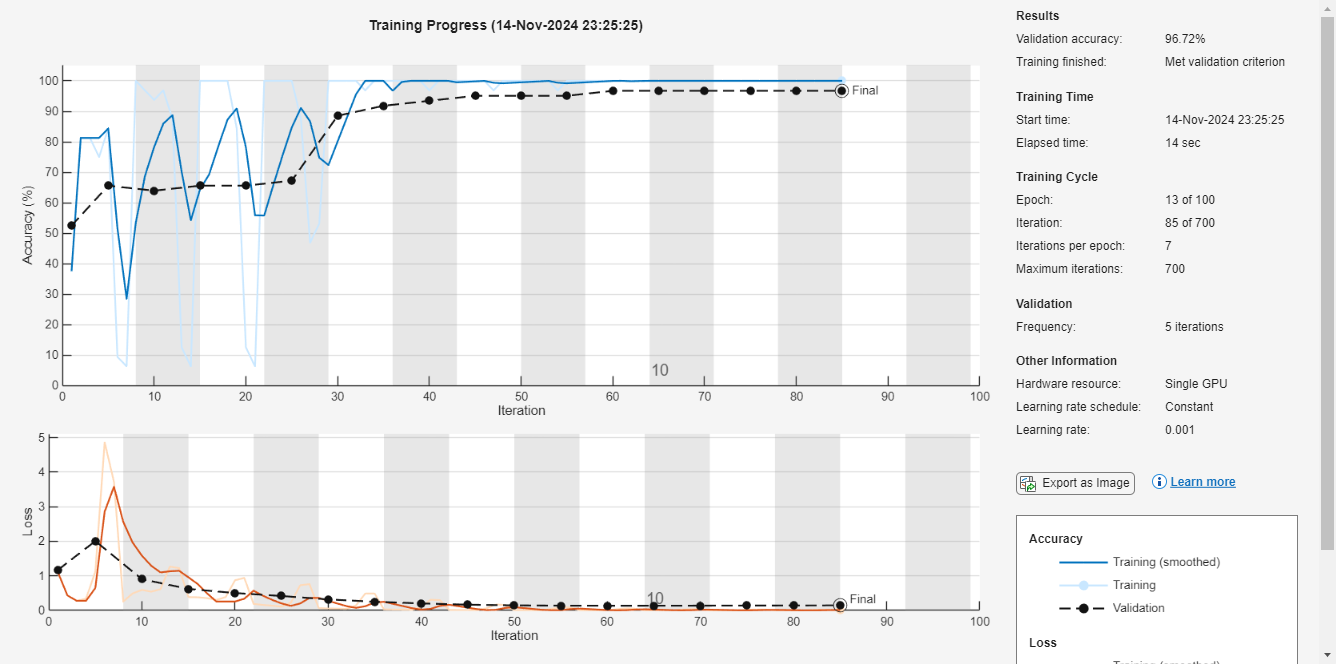

load audio.mat
load labels.mat

features = zeros(size(X, 1), 1003, 14);

for i = 1:size(X, 1)
    features(i, :, :) = ExtractFeatures(X(i, :), 48000);
end

% Define the RNN model
layers = [
    sequenceInputLayer([1003, 14, 1]), ...
    flattenLayer, ...
    lstmLayer(500,'OutputMode','last'), ...   
    reluLayer, ...
    lstmLayer(500,'OutputMode','last'), ...  
    fullyConnectedLayer(3), ...
    softmaxLayer, ...
    classificationLayer ...
];

partition = cvpartition(labels, "HoldOut", 0.2);

idxTrain = training(partition);
idxTest = test(partition);

trainData = features(idxTrain, :, :);
valData = features(idxTest, :, :);

trainLabel = labels(idxTrain);
valLabels = labels(idxTest);

trainData = ConvertToCell(trainData);

valData = ConvertToCell(valData);

% Optionally, you could use a softmax layer if your task is classification.
% For binary classification, use: softmaxLayer followed by a classificationLayer
% For multi-class, you would use a multi-class output size.

options = trainingOptions('adam', ...
    'MaxEpochs', 100, ...
    'MiniBatchSize', 32, ...
    'InitialLearnRate', 0.001, ...
    'Shuffle', 'never', ...
    'Plots', 'training-progress', ...
    'ValidationData', {valData, categorical(valLabels)}, ...
    'ValidationFrequency', 5, ...
    'ValidationPatience', 5 ...
    );


% Train the RNN
net = trainNetwork(trainData, categorical(trainLabel), layers, options);

classNames = categories(categorical(trainLabel));
score = predict(net, {ExtractFeatures(XN1(1, :), 48000)})

score = 1×3 single row vector
    0.0019    0.9981    0.0000


l = scores2label(score, classNames)

l = categorical
     N 


save seriesModel.mat net